## MEAM-5430 Homework 5

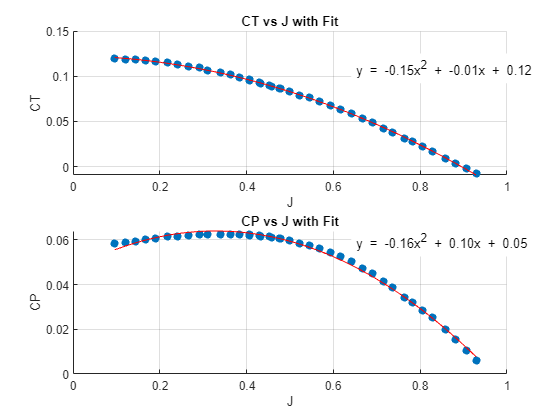

clear;
clc;

T5 = readtable("magf_10x8_pg0725_5969.csv");
T6 = readtable("magf_10x8_pg0726_6007.csv");

J5 = table2array(T5(:,1));
CT5 = table2array(T5(:,2));
CP5 = table2array(T5(:,3));
eta5 = table2array(T5(:,4));

J6 = table2array(T6(:,1));
CT6 = table2array(T6(:,2));
CP6 = table2array(T6(:,3));
eta6 = table2array(T6(:,4));

J = [J5; J6];
CT = [CT5; CT6];
CP = [CP5; CP6];
eta = [eta5; eta6];

CT_J = polyfit(J, CT, 2);
CP_J = polyfit(J, CP, 2);

figure;

% CT vs J
subplot(2,1,1);
scatter(J, CT, 'filled');
hold on;
J_fit = linspace(min(J), max(J), 100);
CT_fit = polyval(CT_J, J_fit);
plot(J_fit, CT_fit, 'r-');
CT_eq = sprintf('y = %.2fx^2 + %.2fx + %.2f', CT_J);
text(max(J_fit)*0.7, max(CT_fit), CT_eq, 'VerticalAlignment', 'top', 'HorizontalAlignment', 'left', 'BackgroundColor', 'white');
title('CT vs J with Fit');
xlabel('J');
ylabel('CT');
grid on;

% CP vs J
subplot(2,1,2);
scatter(J, CP, 'filled');
hold on;
J_fit = linspace(min(J), max(J), 100);
CP_fit = polyval(CP_J, J_fit);
plot(J_fit, CP_fit, 'r-');
CP_eq = sprintf('y = %.2fx^2 + %.2fx + %.2f', CP_J);
text(max(J_fit)*0.7, max(CP_fit), CP_eq, 'VerticalAlignment', 'top', 'HorizontalAlignment', 'left', 'BackgroundColor', 'white');
title('CP vs J with Fit');
xlabel('J');
ylabel('CP');
grid on;

Store the two polyfits, functions are defined at the bottom.

i. Stall speed 6.63m/s

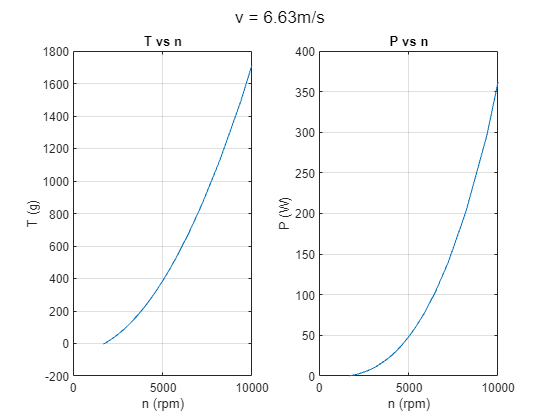

v = 6.63;  % m/s
rho = 1.225;  % kg/m^3
D = 10 * 0.0254;  % m
gear = 3;  % gear ratio

Km = 0.0042;  % Nm/Amp
Rm = 0.25;  % Ohm
i0 = 0.6;  % Amp
e_max = 8.4;  % Volt
e_nom = 6.0;  % Volt

n_rpm = 60 * v / 0.254 ./ J;  % rpm array
n_rpm_2 = n_rpm .* n_rpm;  % rpm^2 array
n_rps_2 = n_rpm_2 / 3600;  % rps^2 array
n_rps_3 = n_rps_2 .* n_rpm / 60;  % rps^3 array

CT_663 = compute_CT(J);
CP_663 = compute_CP(J);
T_n = CT_663 * rho * D^4 .* n_rps_2;  % N
T_n = T_n / 9.8 * 1000;  % g
P_n = CP_663 * rho * D^5 .* n_rps_3;  % W

figure
sgtitle('v = 6.63m/s');

% T vs n
subplot(1,2,1);
plot(n_rpm, T_n);
hold on
title('T vs n');
xlabel('n (rpm)');
xlim([0, 1e4])
ylabel('T (g)');
% ylim([0, 5000])
grid on;

% P vs n
subplot(1,2,2);
plot(n_rpm, P_n);
hold on;
title('P vs n');
xlabel('n (rpm)');
xlim([0, 1e4])
ylabel('P (W)');
grid on;

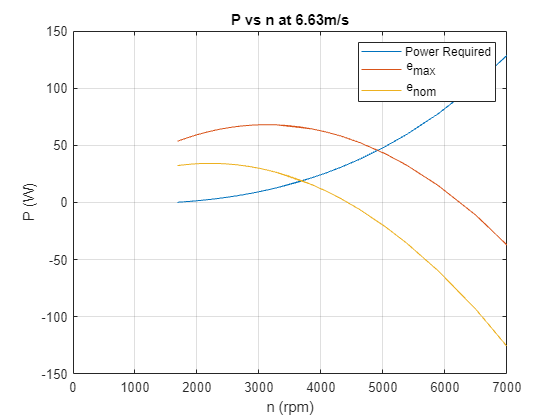

nm_rads = gear * n_rpm / 60 * 2 * pi;  % rad/s
Tm_max = Km * ((e_max - Km * nm_rads) / Rm - i0);  % Nm
Pm_max = Tm_max .* nm_rads;  % W
Tm_nom = Km * ((e_nom - Km * nm_rads) / Rm - i0);  % Nm
Pm_nom = Tm_nom .* nm_rads;  % W

% P vs n
figure
plot(n_rpm, P_n);
hold on;
plot(n_rpm, Pm_max);
hold on;
plot(n_rpm, Pm_nom);
hold on;
title('P vs n at 6.63m/s');
legend('Power Required', 'e_{max}', 'e_{nom}');
xlabel('n (rpm)');
xlim([0, 7e3])
ylabel('P (W)');
grid on;
hold off;

ii. 9.32m/s

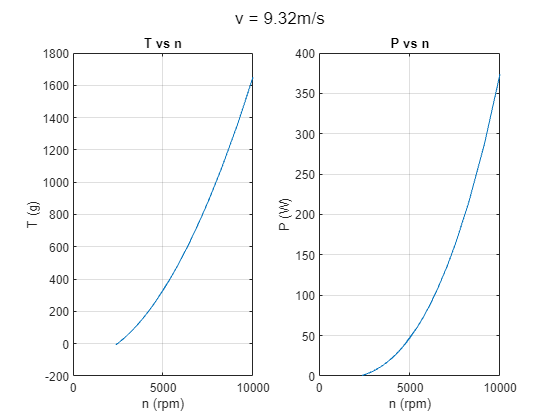

v = 9.32;  % m/s
rho = 1.225;  % kg/m^3
D = 10 * 0.0254;  % m

n_rpm = 60 * v / 0.254 ./ J;  % rpm array
n_rpm_2 = n_rpm .* n_rpm;  % rpm^2 array
n_rps_2 = n_rpm_2 / 3600;  % rps^2 array
n_rps_3 = n_rps_2 .* n_rpm / 60;  % rps^3 array

T_n = compute_CT(J) * rho * D^4 .* n_rps_2;  % N
T_n = T_n / 9.8 * 1000;  % g
P_n = compute_CP(J) * rho * D^5 .* n_rps_3;  % W

figure
sgtitle('v = 9.32m/s');

% T vs n
subplot(1,2,1);
plot(n_rpm, T_n);
hold on;
title('T vs n');
xlabel('n (rpm)');
xlim([0, 1e4])
ylabel('T (g)');
% ylim([0, 7000])
grid on;

% P vs n
subplot(1,2,2);
plot(n_rpm, P_n);
hold on;
title('P vs n');
xlabel('n (rpm)');
xlim([0, 1e4])
ylabel('P (W)');
grid on;

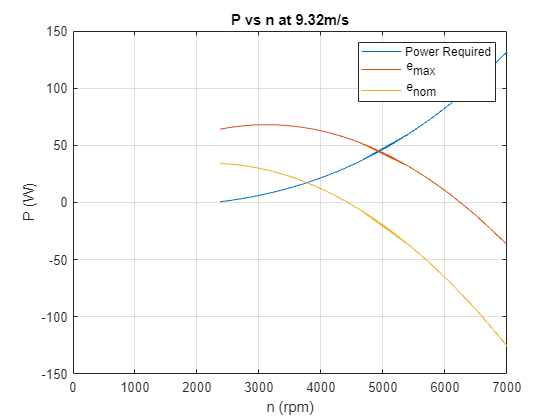

nm_rads = gear * n_rpm / 60 * 2 * pi;  % rad/s
Tm_max = Km * ((e_max - Km * nm_rads) / Rm - i0);  % Nm
Pm_max = Tm_max .* nm_rads;  % W
Tm_nom = Km * ((e_nom - Km * nm_rads) / Rm - i0);  % Nm
Pm_nom = Tm_nom .* nm_rads;  % W

% P vs n
figure
plot(n_rpm, P_n);
hold on;
plot(n_rpm, Pm_max);
hold on;
plot(n_rpm, Pm_nom);
hold on;
title('P vs n at 9.32m/s');
legend('Power Required', 'e_{max}', 'e_{nom}');
xlabel('n (rpm)');
xlim([0, 7e3])
ylabel('P (W)');
grid on;
hold off;

iii. 18.64m/s

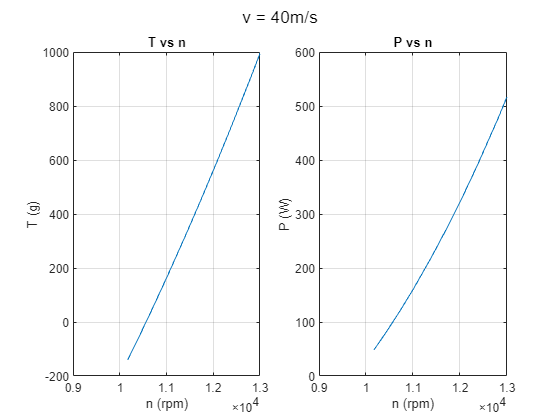

v = 2 * 9.32;  % m/s
v = 40;
rho = 1.225;  % kg/m^3
D = 10 * 0.0254;  % m

n_rpm = 60 * v / 0.254 ./ J;  % rpm array
n_rpm_2 = n_rpm .* n_rpm;  % rpm^2 array
n_rps_2 = n_rpm_2 / 3600;  % rps^2 array
n_rps_3 = n_rps_2 .* n_rpm / 60;  % rps^3 array

T_n = compute_CT(J) * rho * D^4 .* n_rps_2;  % N
T_n = T_n / 9.8 * 1000;  % g
P_n = compute_CP(J) * rho * D^5 .* n_rps_3;  % W

% T_n_fit = polyfit(n_rpm_2, T_n, 1);
% P_n_fit = polyfit(n_rpm_2, P_n, 2);

figure
sgtitle('v = 40m/s');


% T vs n
subplot(1,2,1);
plot(n_rpm, T_n);
hold on;
title('T vs n');
xlabel('n (rpm)');
xlim([0.9e4, 1.3e4])
ylabel('T (g)');
% ylim([0, 6000])
grid on;

% P vs n
subplot(1,2,2);
plot(n_rpm, P_n);
hold on;
title('P vs n');
xlabel('n (rpm)');
xlim([0.9e4, 1.3e4])
ylabel('P (W)');
grid on;

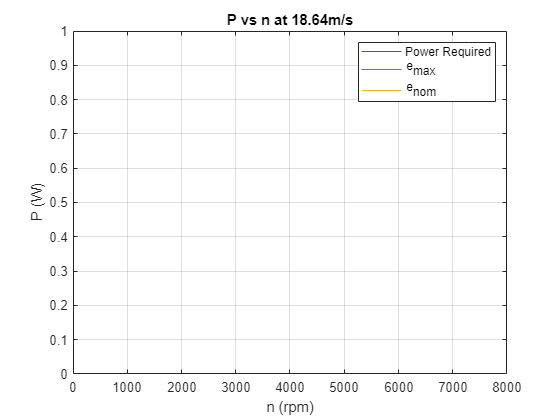

nm_rads = gear * n_rpm / 60 * 2 * pi;  % rad/s
Tm_max = Km * ((e_max - Km * nm_rads) / Rm - i0);  % Nm
Pm_max = Tm_max .* nm_rads;  % W
Tm_nom = Km * ((e_nom - Km * nm_rads) / Rm - i0);  % Nm
Pm_nom = Tm_nom .* nm_rads;  % W

% P vs n
figure
plot(n_rpm, P_n);
hold on;
plot(n_rpm, Pm_max);
hold on;
plot(n_rpm, Pm_nom);
hold on;
title('P vs n at 18.64m/s');
legend('Power Required', 'e_{max}', 'e_{nom}');
xlabel('n (rpm)');
xlim([0, 8e3])
ylabel('P (W)');
grid on;
hold off;

Problem 3

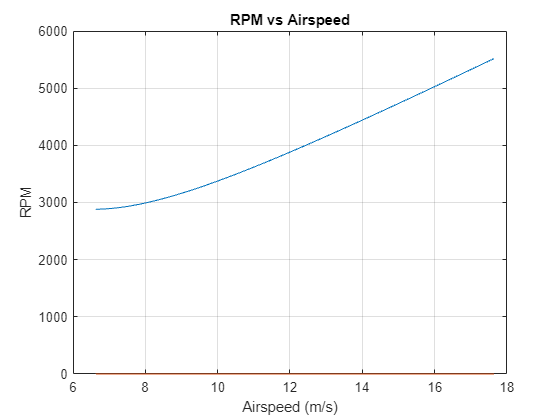

CD0 = 0.03;
K = 0.08;
chord = 0.1905;  % m
W = 7.35;  % N
S = 0.2274189;  % m^2

rho = 1.225;  % kg/m^3
mu = 0.0000181206;

airspeed = linspace(6.63, 17.64, 100);

result_n_rpm = zeros(100);
result_throttle = zeros(100);
result_i = zeros(100);
result_Pe = zeros(100);
result_Pm = zeros(100);
result_Ptotal = zeros(100);
result_eta = zeros(100);
result_etap = zeros(100);
result_etae = zeros(100);
result_vh = zeros(100);

for iter = 1:100
    v = airspeed(iter);
    Re = rho * v * chord / mu;
    
    CL = W / (0.5 * rho * v^2 * S);
    CD = CD0 + K * CL^2;
    Thr = 0.5 * CD * rho * v^2 * S;

    n_rpm = 60 * v / 0.254 ./ J;  % rpm array
    omega = n_rpm / 60 * 2 * pi;  % rad/s array for propeller
    omega_2 = omega .* omega;
    omega_m = gear * omega;  % rad/s array for motor with gear ratio
    n_rpm_2 = n_rpm .* n_rpm;  % rpm^2 array
    n_rps_2 = n_rpm_2 / 3600;  % rps^2 array
    n_rps_3 = n_rps_2 .* n_rpm / 60;  % rps^3 array

    T_n = compute_CT(J) * rho * D^4 .* n_rps_2;  % N
    P_n = compute_CP(J) * rho * D^5 .* n_rps_3;  % W

    T_omega2_fit = polyfit(omega_2, T_n, 1);
    T_omega2_fit(2) = T_omega2_fit(2) - Thr;

    % Find roots in rad/s
    root = roots(T_omega2_fit);

    % Compute rotation speeds
    omega_des = sqrt(root);
    n_rpm_des = omega_des * 60 / 2 / pi;
    n_rpm2_des = n_rpm_des^2;
    n_rps_des = n_rpm_des / 60;

    % Compute power
    J_des = v / n_rps_des / D;
    Pm_des = compute_CP(J_des) * rho * D^5 * n_rps_des^3;

    % Compute motor
    omega_m_des = gear * omega_des;
    e_des = Rm * (Pm_des / Km / omega_m_des + i0) + Km * omega_m_des;
    throttle = e_des / e_max * 100;
    i_des = (e_des - Km * omega_m_des) / Rm;
    P_total_des = e_des * i_des;
    Pe_des = P_total_des - Pm_des;
    eta_e_des = Pm_des / P_total_des;
    eta_p_des = Thr * v / Pm_des;
    eta_des = eta_p_des * eta_e_des;

    % Compute max climb rate
    vh_des = 0;
    n_rpm = 60 * v / 0.254 ./ J;  % rpm array
    n_rpm_2 = n_rpm .* n_rpm;  % rpm^2 array
    n_rps_2 = n_rpm_2 / 3600;  % rps^2 array
    n_rps_3 = n_rps_2 .* n_rpm / 60;  % rps^3 array

    T_n = compute_CT(J) * rho * D^4 .* n_rps_2;  % N
    T_n = T_n / 9.8 * 1000;  % g
    P_n = compute_CP(J) * rho * D^5 .* n_rps_3;  % W

    nm_rads = gear * n_rpm / 60 * 2 * pi;  % rad/s
    Tm_max = Km * ((e_max - Km * nm_rads) / Rm - i0);  % Nm
    Pm_max = Tm_max .* nm_rads;  % W
    Tm_nom = Km * ((e_nom - Km * nm_rads) / Rm - i0);  % Nm
    Pm_nom = Tm_nom .* nm_rads;  % W

    motor_power_curve = polyfit(n_rpm, Pm_max, 3);
    required_power_curve = polyfit(n_rpm, P_n, 3);
    minus = motor_power_curve - required_power_curve;
    root = roots(minus);  % in rpm
    n_rpm_max = 0;
    for root_i = 1:3
        temp = root(root_i, 1);
        if temp > 100 && temp < 12000
            n_rpm_max = temp;
        end
    end

    Pm_max = compute_CP(v / (n_rpm_max / 60) / D) * rho * D^5 * (n_rpm_max / 60)^3;  % W
    vh_des = (Pm_max - Pm_des) / W;  % m/s
    vh_des = vh_des * 60;  % m/min

    % Write in results
    result_n_rpm(iter) = n_rpm_des;
    result_throttle(iter) = throttle;
    result_i(iter) = i_des;
    result_Pe(iter) = Pe_des;
    result_Pm(iter) = Pm_des;
    result_Ptotal(iter) = P_total_des;
    result_eta(iter) = eta_des;
    result_etap(iter) = eta_p_des;
    result_etae(iter) = eta_e_des;
    result_vh(iter) = vh_des;
end

% RPM vs Airspeed
figure;
plot(airspeed, result_n_rpm);
title('RPM vs Airspeed');
xlabel('Airspeed (m/s)');
ylabel('RPM');
grid on;

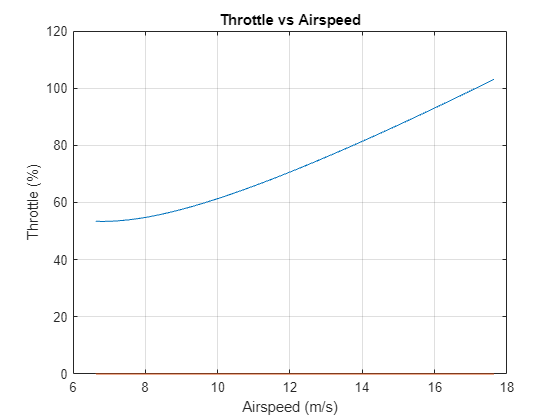


% Throttle vs Airspeed
figure;
plot(airspeed, result_throttle);
title('Throttle vs Airspeed');
xlabel('Airspeed (m/s)');
ylabel('Throttle (%)');
grid on;

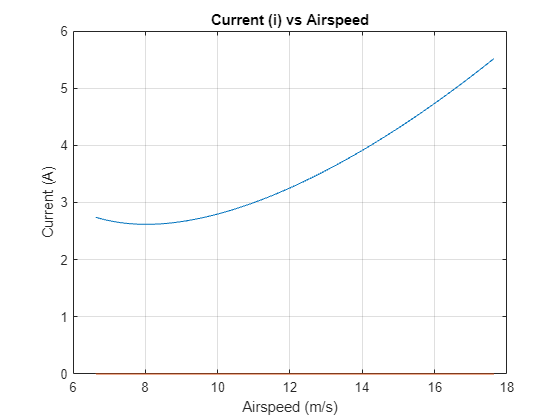


% Current (i) vs Airspeed
figure;
plot(airspeed, result_i);
title('Current (i) vs Airspeed');
xlabel('Airspeed (m/s)');
ylabel('Current (A)');
grid on;

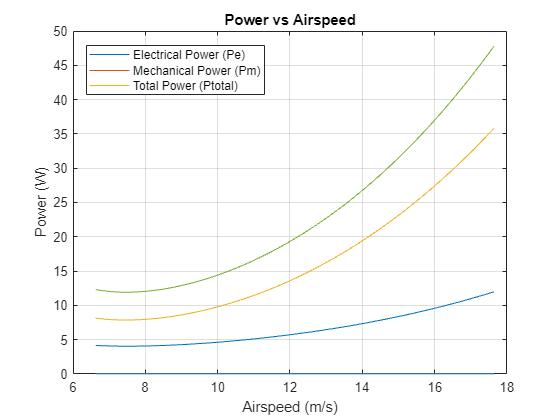


% Power
figure;
plot(airspeed, result_Pe);
hold on;
plot(airspeed, result_Pm);
plot(airspeed, result_Ptotal);
hold off;
title('Power vs Airspeed');
xlabel('Airspeed (m/s)');
ylabel('Power (W)');
legend('Electrical Power (Pe)', 'Mechanical Power (Pm)', 'Total Power (Ptotal)');
legend("Position", [0.15417,0.77302,0.31964,0.11905])
grid on;

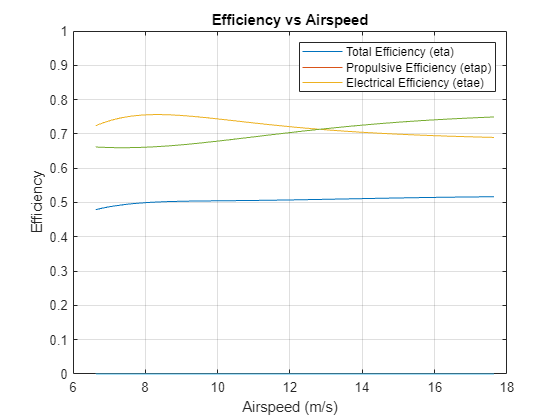

% Efficency
figure;
plot(airspeed, result_eta);
hold on;
plot(airspeed, result_etap);
plot(airspeed, result_etae);
hold off;
title('Efficiency vs Airspeed');
xlabel('Airspeed (m/s)');
ylabel('Efficiency');
ylim([0, 1])
legend('Total Efficiency (eta)', 'Propulsive Efficiency (etap)', 'Electrical Efficiency (etae)');
grid on;

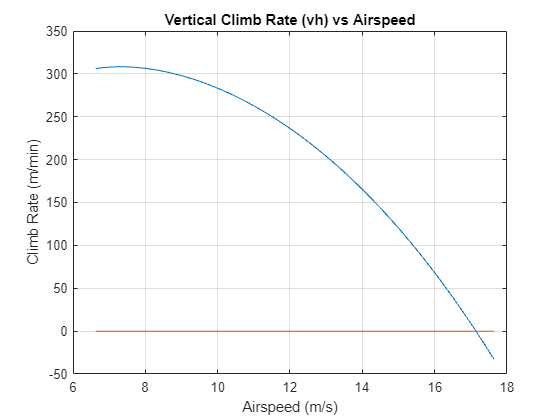


% Vertical Climb Rate (vh) vs Airspeed
figure;
plot(airspeed, result_vh);
title('Vertical Climb Rate (vh) vs Airspeed');
xlabel('Airspeed (m/s)');
ylabel('Climb Rate (m/min)');
grid on;

function result = compute_CT(J)
    result = -0.1454 * J .* J - 0.0070 * J + 0.1226;
end

function result = compute_CP(J)
    result = -0.1561 * J .* J + 0.1026 * J + 0.0471;
end